# Robotics 2 - Final exam - July 11, 2017 

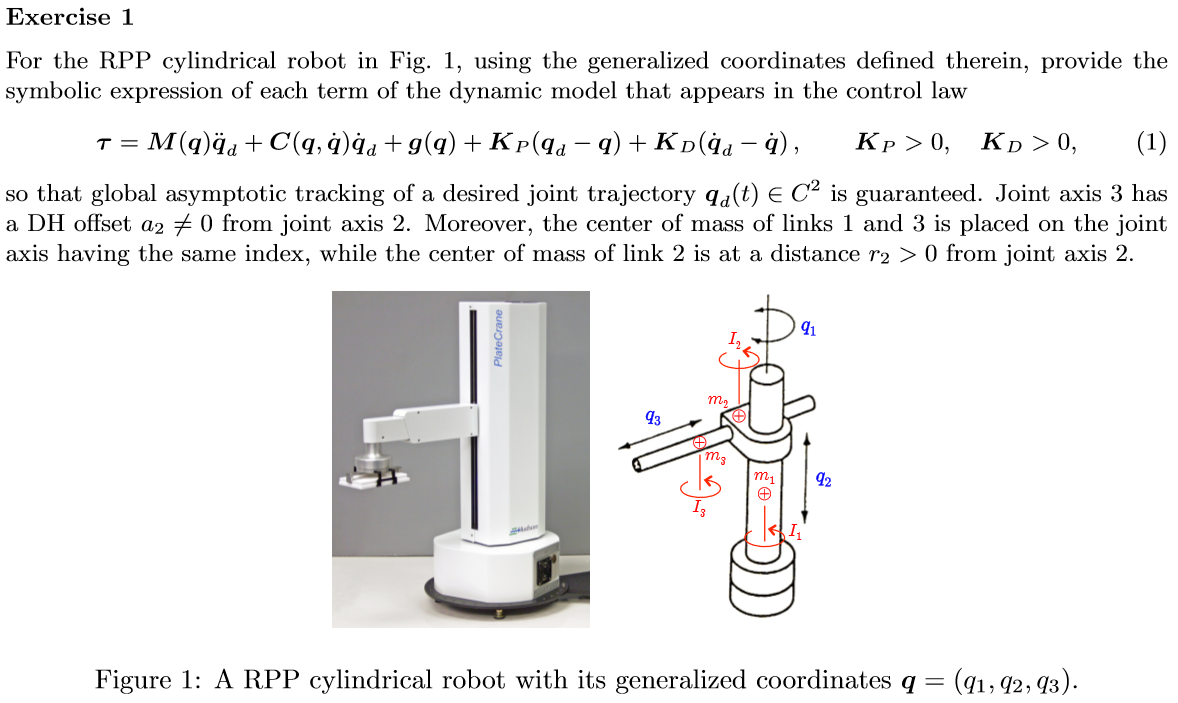

clear;clc

$$ans = m_{2}\,{\cos\left(\alpha \right)}^{2}+\left(m_{1}+m_{2}\right)\,{\sin\left(\alpha \right)}^{2}$$

$$ans = m_{2}\,{\cos\left(\alpha \right)}^{2}+\left(m_{1}+m_{2}\right)\,{\sin\left(\alpha \right)}^{2}$$

$$ans = m_{2}\,{\cos\left(\alpha \right)}^{2}+\left(m_{1}+m_{2}\right)\,{\sin\left(\alpha \right)}^{2}+1$$

$$ans = \mathrm{vd}\,\left(m_{2}\,{\cos\left(\alpha \right)}^{2}+\left(m_{1}+m_{2}\right)\,{\sin\left(\alpha \right)}^{2}\right)+g_{0}\,\sin\left(\alpha \right)\,\left(m_{1}+m_{2}\right)$$

sigma = [0;1;1] % 0: Revolute, 1: Prismatic

sigma =      0
     1
     1


n = length(sigma); %Number of joints

q = sym('q', [n 1]);
qd = sym('qd',[n 1]);
qdd = sym('qdd',[n 1]);
d = sym('d', [n 1]);
a = sym('a', [n 1]);
l = sym('l',[n 1]);
d = sym('d',[n 1]);
m = sym('m',[n 1]);
I = sym('I',[n 1]);
syms g0
g = [0 -g0 0].' 

$$g = \left(\begin{array}{c} 0\\ -g_{0}\\ 0 \end{array}\right)$$

syms r a
% alpha,a, d, theta
dhTable = [0 0 0 q(1);
           -pi/2 r q(2) 0;
           0 0 q(3)+a 0]

$$dhTable = \left(\begin{array}{cccc} 0 & 0 & 0 & q_{1}\\ -\frac{\pi }{2} & r & q_{2} & 0\\ 0 & 0 & a+q_{3} & 0 \end{array}\right)$$

close all
L(1) = Link('a', 0, 'alpha', 0, 'd', 0,'qlim',[0,pi]); % Revolute
L(2) = Link('a', 5, 'alpha',  -pi/2,  'theta', 5,'qlim',[0,20]); % Prismatic
L(3) = Link('a', 0, 'alpha',0,  'theta', 0,'qlim',[0,20]); % Prismatic
prpRobot = SerialLink(L, 'name', 'RPP_Robot ')

 
prpRobot = 
 
RPP_Robot :: 3 axis, RPP, stdDH, slowRNE                         
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          0|          0|          0|          0|
|  2|          5|         q2|          5|    -1.5708|          0|
|  3|          0|         q3|          0|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
 


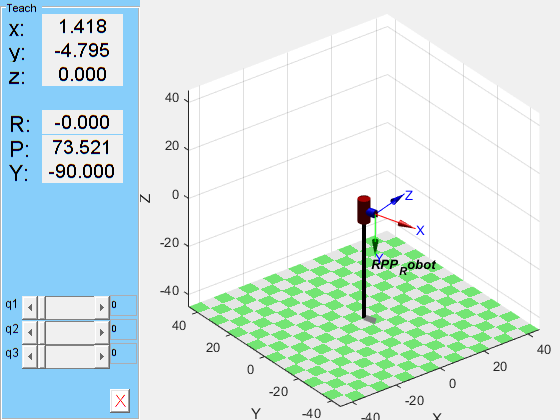

prpRobot.teach

% 

[Ttotal,TPartial] = getTransformationMatrix(dhTable,'alpha')

$$Ttotal = \left(\begin{array}{cccc} \cos\left(q_{1}\right) & 0 & -\sin\left(q_{1}\right) & r\,\cos\left(q_{1}\right)-\sin\left(q_{1}\right)\,\left(a+q_{3}\right)\\ \sin\left(q_{1}\right) & 0 & \cos\left(q_{1}\right) & \cos\left(q_{1}\right)\,\left(a+q_{3}\right)+r\,\sin\left(q_{1}\right)\\ 0 & -1 & 0 & q_{2}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

TPartial = 1×3 cell array
    {4×4 sym}    {4×4 sym}    {4×4 sym}


Taccum = eye(4) 

Taccum =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


for i = 1:n
    Taccum = Taccum*TPartial{i}
end

$$Taccum = \left(\begin{array}{cccc} \cos\left(q_{1}\right) & -\sin\left(q_{1}\right) & 0 & 0\\ \sin\left(q_{1}\right) & \cos\left(q_{1}\right) & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$Taccum = \left(\begin{array}{cccc} \cos\left(q_{1}\right) & 0 & -\sin\left(q_{1}\right) & r\,\cos\left(q_{1}\right)\\ \sin\left(q_{1}\right) & 0 & \cos\left(q_{1}\right) & r\,\sin\left(q_{1}\right)\\ 0 & -1 & 0 & q_{2}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$Taccum = \left(\begin{array}{cccc} \cos\left(q_{1}\right) & 0 & -\sin\left(q_{1}\right) & r\,\cos\left(q_{1}\right)-\sin\left(q_{1}\right)\,\left(a+q_{3}\right)\\ \sin\left(q_{1}\right) & 0 & \cos\left(q_{1}\right) & \cos\left(q_{1}\right)\,\left(a+q_{3}\right)+r\,\sin\left(q_{1}\right)\\ 0 & -1 & 0 & q_{2}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

% Script to create time dependent variables
var_ind = 't';
var_dep = 'q';
var_set =[]


var_set =

     []



syms(var_ind)
for i=1:n
   var_dep_str = strcat(var_dep,num2str(i),'(',var_ind,')');
   syms(var_dep_str);
   var_set = [var_set str2sym(var_dep_str)]; % appends the variable to the set
end
qt = var_set.'

$$qt = \left(\begin{array}{c} q_{1}\left(t\right)\\ q_{2}\left(t\right)\\ q_{3}\left(t\right) \end{array}\right)$$

p = {}


p =

  0×0 empty cell array



v = {}


v =

  0×0 empty cell array



T = {}


T =

  0×0 empty cell array



Taccum = eye(4) 

Taccum =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


KEsubs = 0

KEsubs = 0

for i = 1:n
    Taccum = Taccum*TPartial{i}
    p{i} = subs(Taccum(1:3,4),q,qt)
    v{i} = diff(p{i},t)
    
    T{i} = simplify(0.5*m(i)*v{i}.'*v{i})
    
    Tsubs{i} = subs(T{i} ,diff(qt),qd)
    Tsubs{i} = subs(Tsubs{i},qt,q) + 0.5*I(i)*qd(1)^2
    KEsubs = KEsubs + Tsubs{i}
end

$$Taccum = \left(\begin{array}{cccc} \cos\left(q_{1}\right) & -\sin\left(q_{1}\right) & 0 & 0\\ \sin\left(q_{1}\right) & \cos\left(q_{1}\right) & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

p = 1×1 cell array
    {3×1 sym}


v = 1×1 cell array
    {3×1 sym}


T = 1×1 cell array
    {1×1 sym}


Tsubs = 1×3 cell array
    {1×1 sym}    {1×1 sym}    {1×1 sym}


Tsubs = 1×3 cell array
    {1×1 sym}    {1×1 sym}    {1×1 sym}


$$KEsubs = \frac{I_{1}\,{{\mathrm{qd}}_{1}}^{2}}{2}$$

$$Taccum = \left(\begin{array}{cccc} \cos\left(q_{1}\right) & 0 & -\sin\left(q_{1}\right) & r\,\cos\left(q_{1}\right)\\ \sin\left(q_{1}\right) & 0 & \cos\left(q_{1}\right) & r\,\sin\left(q_{1}\right)\\ 0 & -1 & 0 & q_{2}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

p = 1×2 cell array
    {3×1 sym}    {3×1 sym}


v = 1×2 cell array
    {3×1 sym}    {3×1 sym}


T = 1×2 cell array
    {1×1 sym}    {1×1 sym}


Tsubs = 1×3 cell array
    {1×1 sym}    {1×1 sym}    {1×1 sym}


Tsubs = 1×3 cell array
    {1×1 sym}    {1×1 sym}    {1×1 sym}


$$KEsubs = \frac{I_{1}\,{{\mathrm{qd}}_{1}}^{2}}{2}+\frac{I_{2}\,{{\mathrm{qd}}_{1}}^{2}}{2}+\frac{m_{2}\,{{\mathrm{qd}}_{2}}^{2}}{2}+\frac{m_{2}\,{{\mathrm{qd}}_{1}}^{2}\,r^{2}}{2}$$

$$Taccum = \left(\begin{array}{cccc} \cos\left(q_{1}\right) & 0 & -\sin\left(q_{1}\right) & r\,\cos\left(q_{1}\right)-\sin\left(q_{1}\right)\,\left(a+q_{3}\right)\\ \sin\left(q_{1}\right) & 0 & \cos\left(q_{1}\right) & \cos\left(q_{1}\right)\,\left(a+q_{3}\right)+r\,\sin\left(q_{1}\right)\\ 0 & -1 & 0 & q_{2}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

p = 1×3 cell array
    {3×1 sym}    {3×1 sym}    {3×1 sym}


v = 1×3 cell array
    {3×1 sym}    {3×1 sym}    {3×1 sym}


T = 1×3 cell array
    {1×1 sym}    {1×1 sym}    {1×1 sym}


Tsubs = 1×3 cell array
    {1×1 sym}    {1×1 sym}    {1×1 sym}


Tsubs = 1×3 cell array
    {1×1 sym}    {1×1 sym}    {1×1 sym}


$$KEsubs = \frac{m_{3}\,{\left({\mathrm{qd}}_{3}\,\cos\left(q_{1}\right)+{\mathrm{qd}}_{1}\,r\,\cos\left(q_{1}\right)-{\mathrm{qd}}_{1}\,\sin\left(q_{1}\right)\,\left(a+q_{3}\right)\right)}^{2}}{2}+\frac{m_{3}\,{\left({\mathrm{qd}}_{3}\,\sin\left(q_{1}\right)+{\mathrm{qd}}_{1}\,r\,\sin\left(q_{1}\right)+{\mathrm{qd}}_{1}\,\cos\left(q_{1}\right)\,\left(a+q_{3}\right)\right)}^{2}}{2}+\frac{I_{1}\,{{\mathrm{qd}}_{1}}^{2}}{2}+\frac{I_{2}\,{{\mathrm{qd}}_{1}}^{2}}{2}+\frac{I_{3}\,{{\mathrm{qd}}_{1}}^{2}}{2}+\frac{m_{2}\,{{\mathrm{qd}}_{2}}^{2}}{2}+\frac{m_{3}\,{{\mathrm{qd}}_{2}}^{2}}{2}+\frac{m_{2}\,{{\mathrm{qd}}_{1}}^{2}\,r^{2}}{2}$$

% I'm not gettin gthe exact same answer as the provided solution.

Error using sum
Invalid data type. First argument must be numeric or logical.

M = getInertiaMatrixFromKE(KEsubs,qd)

$$M = \left(\begin{array}{ccc} I_{1}+I_{2}+I_{3}+a^{2}\,m_{3}+m_{3}\,{q_{3}}^{2}+m_{2}\,r^{2}+m_{3}\,r^{2}+2\,a\,m_{3}\,q_{3} & 0 & m_{3}\,r\\ 0 & m_{2}+m_{3} & 0\\ m_{3}\,r & 0 & m_{3} \end{array}\right)$$

[KE,T]= getKEwithJacobian(dhTable,sigma,q,qd,l,m,I,d,0)

*** Computation of Kinetic Energy (Jacobian-based method) 


$$KE = \frac{I_{1}\,{{\mathrm{qd}}_{1}}^{2}}{2}+\frac{I_{2}\,{{\mathrm{qd}}_{1}}^{2}}{2}+\frac{I_{3}\,{{\mathrm{qd}}_{1}}^{2}}{2}+\frac{m_{2}\,{{\mathrm{qd}}_{2}}^{2}}{2}+\frac{m_{3}\,{{\mathrm{qd}}_{2}}^{2}}{2}+\frac{m_{3}\,{{\mathrm{qd}}_{3}}^{2}}{2}+\frac{a^{2}\,m_{3}\,{{\mathrm{qd}}_{1}}^{2}}{2}+\frac{m_{3}\,{q_{3}}^{2}\,{{\mathrm{qd}}_{1}}^{2}}{2}+\frac{m_{2}\,{{\mathrm{qd}}_{1}}^{2}\,r^{2}}{2}+\frac{m_{3}\,{{\mathrm{qd}}_{1}}^{2}\,r^{2}}{2}+m_{3}\,{\mathrm{qd}}_{1}\,{\mathrm{qd}}_{3}\,r+a\,m_{3}\,q_{3}\,{{\mathrm{qd}}_{1}}^{2}$$

T = 1×3 cell array
    {1×1 sym}    {1×1 sym}    {1×1 sym}


for i = 1:n
    T{i}
end

$$ans = \frac{I_{1}\,{{\mathrm{qd}}_{1}}^{2}}{2}$$

$$ans = \frac{m_{2}\,{{\mathrm{qd}}_{1}}^{2}\,r^{2}}{2}+\frac{I_{2}\,{{\mathrm{qd}}_{1}}^{2}}{2}+\frac{m_{2}\,{{\mathrm{qd}}_{2}}^{2}}{2}$$

$$ans = \frac{m_{3}\,a^{2}\,{{\mathrm{qd}}_{1}}^{2}}{2}+m_{3}\,a\,q_{3}\,{{\mathrm{qd}}_{1}}^{2}+\frac{m_{3}\,{q_{3}}^{2}\,{{\mathrm{qd}}_{1}}^{2}}{2}+\frac{m_{3}\,{{\mathrm{qd}}_{1}}^{2}\,r^{2}}{2}+\frac{I_{3}\,{{\mathrm{qd}}_{1}}^{2}}{2}+m_{3}\,{\mathrm{qd}}_{1}\,{\mathrm{qd}}_{3}\,r+\frac{m_{3}\,{{\mathrm{qd}}_{2}}^{2}}{2}+\frac{m_{3}\,{{\mathrm{qd}}_{3}}^{2}}{2}$$

M = getInertiaMatrixFromKE(KE,qd)

$$M = \left(\begin{array}{ccc} I_{1}+I_{2}+I_{3}+a^{2}\,m_{3}+m_{3}\,{q_{3}}^{2}+m_{2}\,r^{2}+m_{3}\,r^{2}+2\,a\,m_{3}\,q_{3} & 0 & m_{3}\,r\\ 0 & m_{2}+m_{3} & 0\\ m_{3}\,r & 0 & m_{3} \end{array}\right)$$

## Exercise 2

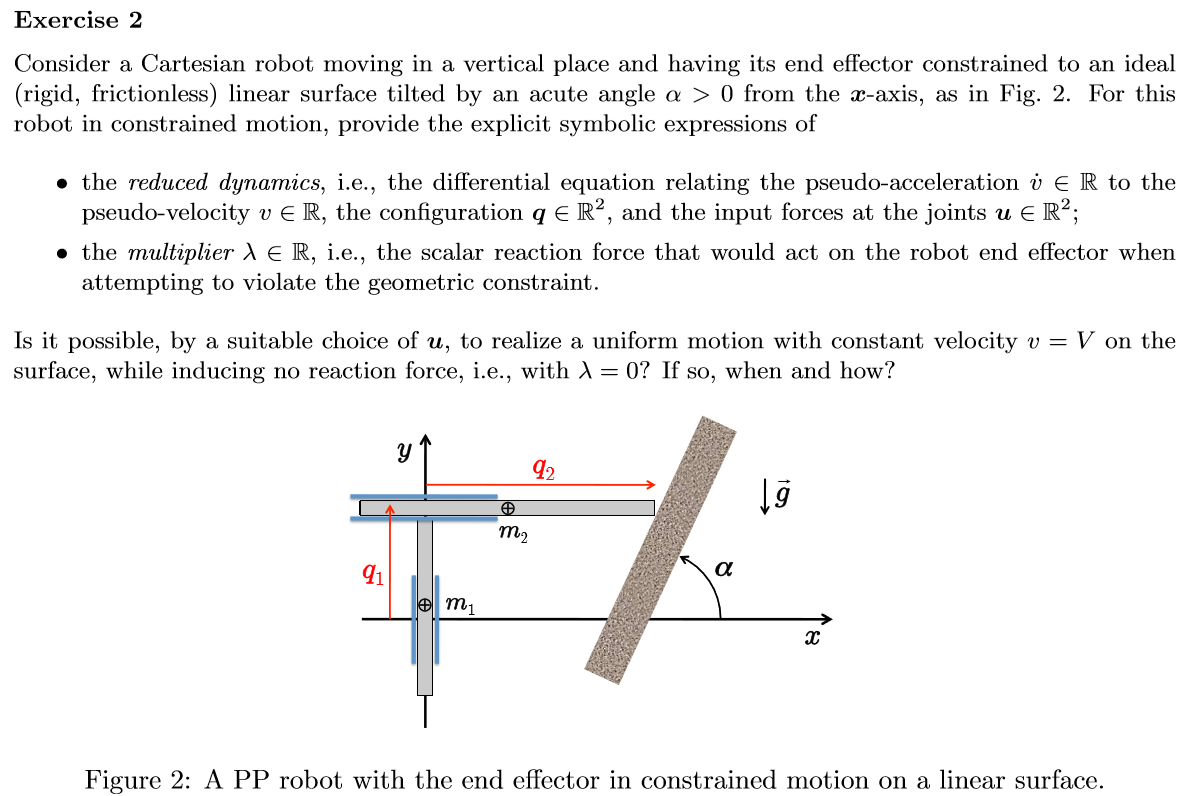

clear;clc
sigma = [1;1] % 0: Revolute, 1: Prismatic

sigma =      1
     1


n = length(sigma); %Number of joints

q = sym('q', [n 1]);
qd = sym('qd',[n 1]);
qdd = sym('qdd',[n 1]);
d = sym('d', [n 1]);
l = sym('l',[n 1]);
d = sym('d',[n 1]);
m = sym('m',[n 1]);
I = sym('I',[n 1]);
syms g0
g = [0 0 g0].' 

$$g = \left(\begin{array}{c} 0\\ 0\\ g_{0} \end{array}\right)$$

syms r a
% alpha,a, d, theta
% relative coordinates 
dhTable = [-pi/2 0 q(1) 0;
           0 0 q(2) 0]

$$dhTable = \left(\begin{array}{cccc} -\frac{\pi }{2} & 0 & q_{1} & 0\\ 0 & 0 & q_{2} & 0 \end{array}\right)$$

[KE, T] = getKEwithJacobian(dhTable,sigma,q,qd,l,m,I,d,0)

*** Computation of Kinetic Energy (Jacobian-based method) 


$$KE = \frac{m_{1}\,{{\mathrm{qd}}_{1}}^{2}}{2}+\frac{m_{2}\,\left({{\mathrm{qd}}_{1}}^{2}+{{\mathrm{qd}}_{2}}^{2}\right)}{2}$$

T = 1×2 cell array
    {1×1 sym}    {1×1 sym}


M = getInertiaMatrixFromKE(KE,qd)

$$M = \left(\begin{array}{cc} m_{1}+m_{2} & 0\\ 0 & m_{2} \end{array}\right)$$

g_q = getGravityWithJacobian(dhTable,q,l,m,d,g,0)

*** Computation of Potential Energy (Jacobian-based method) 


$$g\_q = \left(\begin{array}{c} g_{0}\,\left(m_{1}+m_{2}\right)\\ 0 \end{array}\right)$$

u = M*qdd + g_q % Result given just like in the example

$$u = \left(\begin{array}{c} {\mathrm{qdd}}_{1}\,\left(m_{1}+m_{2}\right)+g_{0}\,\left(m_{1}+m_{2}\right)\\ m_{2}\,{\mathrm{qdd}}_{2} \end{array}\right)$$

### Task - dynamic constraint

syms alpha k0 v vd
r = [q(2); q(1)]

$$r = \left(\begin{array}{c} q_{2}\\ q_{1} \end{array}\right)$$

k = @(r)(r(1)*sin(alpha) - r(2)*cos(alpha) + k0)

k = function_handle with value:
    @(r)(r(1)*sin(alpha)-r(2)*cos(alpha)+k0)


A = jacobian(k(r),q)

$$A = \left(\begin{array}{cc} -\cos\left(\alpha \right) & \sin\left(\alpha \right) \end{array}\right)$$

D = [sin(alpha) , cos(alpha)]

$$D = \left(\begin{array}{cc} \sin\left(\alpha \right) & \cos\left(\alpha \right) \end{array}\right)$$

EF = simplify(inv([A;D]))

$$EF = \left(\begin{array}{cc} -\cos\left(\alpha \right) & \sin\left(\alpha \right)\\ \sin\left(\alpha \right) & \cos\left(\alpha \right) \end{array}\right)$$

F = EF(:,2)

$$F = \left(\begin{array}{c} \sin\left(\alpha \right)\\ \cos\left(\alpha \right) \end{array}\right)$$

TT = simplify((F.'*M*F)*(vd) + F.'*g_q)

$$TT = \mathrm{vd}\,\left(m_{1}\,{\sin\left(\alpha \right)}^{2}+m_{2}\right)+g_{0}\,\sin\left(\alpha \right)\,\left(m_{1}+m_{2}\right)$$